## Import fatigue data 

clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_");

## Parameter estimation using MLE - Own implementation

% parameter names from matlab documentation:
% https://www.mathworks.com/help/releases/R2025b/stats/lognormal-distribution.html 

% mu = mean of logarithmic values
% sigma = standard deviation of logarithmic values
% MLE - Own implementation

stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels);
% arrays to store parameter estimates
mu_estimates = zeros(num_stress_levels, 1);
sigma_estimates = zeros(num_stress_levels,1);

B1_lives_2PL = zeros(num_stress_levels,1);
for i = 1:num_stress_levels
    life_i = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(i));
    num_observations = numel(life_i);
    log_cycles = log(life_i);
    mu_est = 1/num_observations * sum(log_cycles);
    var_est = 1/num_observations * sum((log_cycles - mu_est).^2);
    sigma_est = sqrt(var_est);
    % calculating the B1 life
    B1_2PL = exp(mu_est + (sigma_est * norminv(0.01)));
    B1_lives_2PL(i) = B1_2PL;
    % store parameters from own implementation at each stress level
    mu_estimates(i) = mu_est;
    sigma_estimates(i) = sigma_est;
end
% display the parameter estimates and B1 lives from own mle implementation
mu_estimates

mu_estimates =    19.1603
   18.1971
   17.5264
   16.6718


sigma_estimates

sigma_estimates =     1.0992
    1.0889
    0.9552
    1.4597


B1_lives_2PL

B1_lives_2PL = 1.0e+07 *

    1.6244
    0.6350
    0.4432
    0.0583


## Parameter estimation using MLE - MATLAB in-built 


% store the matlab mle parameter estimates + B1 lives
mu_estimates_matlab = zeros(num_stress_levels,1);
sigma_estimates_matlab = zeros(num_stress_levels,1);
B1_lives_matlab = zeros(num_stress_levels,1);

% stores the MATLAB fitted distributions for later plotting
pd_2PL_all = cell(num_stress_levels, 1);
for k = 1:num_stress_levels
    life_k = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(k));
    params_2PL_matlab = mle(life_k, 'distribution','Lognormal');
    % store parameters from matlab at each stress level
    mu_estimates_matlab(k) = params_2PL_matlab(1);
    sigma_estimates_matlab(k) = params_2PL_matlab(2);

    % make a distribution object to calculate the B1 life in the next line, mle returns parameters that's why
    pd_2PL = makedist('Lognormal','mu',mu_estimates_matlab(k),'sigma',sigma_estimates_matlab(k));
    pd_2PL_all{k} = pd_2PL;
    B1_2PL_matlab = icdf(pd_2PL, 0.01);
    B1_lives_matlab(k) = B1_2PL_matlab;

    % hazard function behaviour check 
    max_obs_k = max(life_k);
    min_obs_k = min(life_k);
    n_star_MLE = exp(mu_estimates_matlab(k) - (sigma_estimates_matlab(k) ^ 2));

    % Classify where N* falls relative to the observed life range
    if n_star_MLE > max_obs_k
        n_star_region = 'above the observed range (all data in increasing-hazard region)';
    elseif n_star_MLE < min_obs_k
        n_star_region = 'below the observed range (all data in declining-hazard region)';
    else
        pct_above = mean(life_k > n_star_MLE) * 100;
        n_star_region = sprintf('within the observed range (%.1f%% of observations above N*)', pct_above);
    end

    fprintf('Stress level %d: N* = %.1f | observed: %.1f to %.1f | N* lies %s\n',k, n_star_MLE, min_obs_k, max_obs_k, n_star_region);
end

Stress level 1: N* = 62589655.9 | observed: 22500000.0 to 1390000000.0 | N* lies within the observed range (85.7% of observations above N*)
Stress level 2: N* = 24432800.5 | observed: 8770000.0 to 520000000.0 | N* lies within the observed range (85.7% of observations above N*)
Stress level 3: N* = 16420492.3 | observed: 5880000.0 to 211000000.0 | N* lies within the observed range (78.6% of observations above N*)
Stress level 4: N* = 2065841.2 | observed: 1630000.0 to 179000000.0 | N* lies within the observed range (92.9% of observations above N*)



mu_estimates_matlab

mu_estimates_matlab =    19.1603
   18.1971
   17.5264
   16.6718


sigma_estimates_matlab

sigma_estimates_matlab =     1.0992
    1.0889
    0.9552
    1.4597


B1_lives_matlab

B1_lives_matlab = 1.0e+07 *

    1.6244
    0.6350
    0.4432
    0.0583


## Compare the estimates from own implementation and MATLAB built-in

%% Compare the estimates from own implementation and MATLAB built-in

MLE_comparison = table(stress_levels, mu_estimates,mu_estimates_matlab, sigma_estimates, sigma_estimates_matlab, B1_lives_2PL, B1_lives_matlab, 'VariableNames', {'Stress_MPa', 'Mu_Own_MLE','Mu_MATLAB_MLE','Sigma_Own_MLE','Sigma_MATLAB_MLE', 'B1_Own_MLE', 'B1_MATLAB_MLE'})

MLE_comparison = 4×7 table
    Stress_MPa    Mu_Own_MLE    Mu_MATLAB_MLE    Sigma_Own_MLE    Sigma_MATLAB_MLE    B1_Own_MLE    B1_MATLAB_MLE
    __________    __________    _____________    _____________    ________________    __________    _____________

       4900          19.16          19.16            1.0992            1.0992         1.6244e+07     1.6244e+07  
       5500         18.197         18.197            1.0889            1.0889         6.3501e+06     6.3501e+06  
       6100         17.526         17.526           0.95516           0.95516         4.4319e+06     4.4319e+06  
       6700         16.672         16.672            1.4597            1.4597         5.8304e+05     5.8304e+05  


## PPLR and GoF (Anderson-Darling)

dF_tail =     0.0274
    0.0556
    0.0466


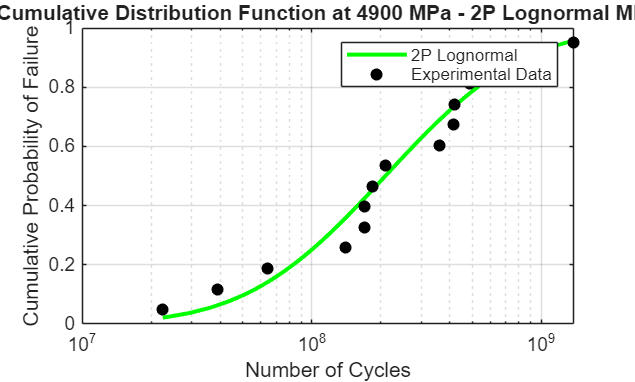

Stress level 1: N* = 49266792.5 | observed: 22500000.0 to 1390000000.0 | N* lies within the observed range (85.7% of observations above N*)


dF_tail =     0.0274
    0.0559
    0.0464


Stress level 2: N* = 19319758.1 | observed: 8770000.0 to 520000000.0 | N* lies within the observed range (85.7% of observations above N*)


dF_tail =     0.0275
    0.0558
    0.0470


Stress level 3: N* = 13708967.0 | observed: 5880000.0 to 211000000.0 | N* lies within the observed range (85.7% of observations above N*)


dF_tail =    -0.0038
    0.0091
    0.0422


Stress level 4: N* = 1394106.2 | observed: 1630000.0 to 179000000.0 | N* lies below the observed range (all data in declining-hazard region)


% rank equation matrices

% Median rank plotting positions
% F_i = (i - 0.3)/(n + 0.4)

r_max_array = zeros(num_stress_levels, 1);
max_rank_eq = zeros(num_stress_levels, 2);
mu_estimates_PPLR = zeros(num_stress_levels, 1);

sigma_estimates_PPLR = zeros(num_stress_levels, 1);
rank_equation = strings(num_stress_levels, 1);

% anderson-darling info
p = zeros(num_stress_levels, 1);
ad_test = zeros(num_stress_levels, 1);
ad_h = zeros(num_stress_levels, 1);
ad_cv = zeros(num_stress_levels, 1);

% stores the experimental plotting data and fitted CDFs for later plotting
cdf_x = cell(num_stress_levels, 1);
cdf_mle = cell(num_stress_levels, 1);
cdf_life_sorted = cell(num_stress_levels, 1);
cdf_empirical_F = cell(num_stress_levels, 1);

% stores the regression data for later plotting
probability_X = cell(num_stress_levels, 1);
probability_Y = cell(num_stress_levels, 1);
probability_Y_fit = cell(num_stress_levels, 1);

% tail fit check storage 
tail_fit_lives = cell(num_stress_levels,1);
tail_fit_dF = cell(num_stress_levels,1);
tail_fit_abs_dF = cell(num_stress_levels,1);
tail_fit_F_empirical = cell(num_stress_levels,1);
tail_fit_dF_PPLR = cell(num_stress_levels,1);
tail_fit_abs_dF_PPLR = cell(num_stress_levels,1);

for j = 1:num_stress_levels
    %j
    current_stress = stress_levels(j);
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(j)); % extract the number of cycles for the current stress level
    num_observations_j = numel(life_j);
    life_j_sorted = sort(life_j); % sorts the lives in asending order
    X_j = log10(life_j_sorted); % calculates the X values for the linearised 2P Lognormal form
    observation_ranks = (1:num_observations_j)';

    % Median rank plotting positions
    F = (observation_ranks - 0.3) ./ (num_observations_j + 0.4);

    % Exclude invalid endpoint probabilities before transforming
    valid_positions_mxg = (F > 0) & (F < 1);

    F_mxg = F(valid_positions_mxg);
    X_j_valid = X_j(valid_positions_mxg);

    Y_j = norminv(F_mxg);

    % Calculate correlation coefficient
    r_2PL_matrix = corrcoef(X_j_valid, Y_j);
    max_r = r_2PL_matrix(1, 2);

    r_max_array(j) = max_r;
    rank_equation(j) = "Median Rank";
    % plot the regression to see transformed data against fitted line
    fitted_line = polyfit(Y_j, X_j_valid, 1);
    reg_slope = fitted_line(1);
    reg_intercept = fitted_line(2);

    % convert the regression parameters from log10 cycles to natural-log parameters
    sigma_est_PPLR = reg_slope * log(10);
    mu_est_PPLR = reg_intercept * log(10);
    % store the parameter estimates for PPLR
    mu_estimates_PPLR(j) = mu_est_PPLR;
    sigma_estimates_PPLR(j) = sigma_est_PPLR;

    % store the regression data for later plotting
    Y_fit = reg_slope * Y_j + reg_intercept;
    probability_X{j} = X_j_valid;
    probability_Y{j} = Y_j;
    probability_Y_fit{j} = Y_fit;

    % Plot the mle cdf and use the probability plotting from above for experimental data
    life_j_lin = linspace(min(life_j), max(life_j), 200);
    cdf_2PL_mle = logncdf(life_j_lin, mu_estimates_matlab(j), sigma_estimates_matlab(j)); % plot the cdf for parameter estimates mu and sigma at stress level j
    % store the CDF data for later plotting
    cdf_x{j} = life_j_lin;
    cdf_mle{j} = cdf_2PL_mle;
    cdf_life_sorted{j} = life_j_sorted(valid_positions_mxg);
    cdf_empirical_F{j} = F_mxg;

    % Tail-fit check at the 3 lowest observed fatigue lives
    N_tail = life_j_sorted(1:3);
    F_empirical_tail = F(1:3);
    F_predicted_tail = logncdf(N_tail, mu_estimates_matlab(j), sigma_estimates_matlab(j));
    tail_fit_F_empirical{j} = F_empirical_tail;
    dF_tail = F_empirical_tail - F_predicted_tail
    abs_dF_tail = abs(dF_tail);

    % Store results for each stress level
    tail_fit_lives{j} = N_tail;
    tail_fit_dF{j} = dF_tail;
    tail_fit_abs_dF{j} = abs_dF_tail;

    % Tail-fit check using PPLR parameter estimates
    F_predicted_tail_PPLR = logncdf( ...
        N_tail, mu_estimates_PPLR(j), sigma_estimates_PPLR(j));

    dF_tail_PPLR = F_empirical_tail - F_predicted_tail_PPLR;
    abs_dF_tail_PPLR = abs(dF_tail_PPLR);

    % Store PPLR tail-fit differences
    tail_fit_dF_PPLR{j} = dF_tail_PPLR;
    tail_fit_abs_dF_PPLR{j} = abs_dF_tail_PPLR;

    % CDF plot
    figure
    plot(life_j_lin, cdf_2PL_mle, 'Color', 'g', 'LineWidth', 2, 'LineStyle','-');
    hold on
    scatter(life_j_sorted(valid_positions_mxg), F_mxg, 'filled', 'o','k');
    xlabel('Number of Cycles');
    ylabel('Cumulative Probability of Failure');
    title(sprintf('Cumulative Distribution Function at %d MPa - 2P Lognormal MLE', current_stress)); % got assitance on writing this line from chatgpt, recommended sprintf ** intially tried to concatenate which didn't work
    legend('2P Lognormal', 'Experimental Data');
    set(gca,'xscale','log');
    grid on
    hold off
    % conduct an anderson-darling GoF test
    clear adtest % adtest got initialised as a variable for some reason, this clears it to avoid errors
    [h, p_value, test_stat, cv] = adtest(life_j,"Distribution","logn"); % for unspecified parameters for the lognormal distribution, returns h (rejects or accepts the null hypothesis, p-value, the test statistic ad the critical value
    p(j) = p_value;
    ad_test(j) = test_stat;
    ad_h(j) = h;
    ad_cv(j) = cv;

    % hazard function behaviour 
    max_obs_j = max(life_j);
    min_obs_j = min(life_j);
    n_star_PPLR = exp(mu_est_PPLR - (sigma_est_PPLR ^ 2));

    % classify where N* falls 
    if n_star_PPLR > max_obs_j
        n_star_region_PPLR = 'above the observed range (all data in increasing-hazard region)';
    elseif n_star_PPLR < min_obs_j
        n_star_region_PPLR = 'below the observed range (all data in declining-hazard region)';
    else
        pct_above = mean(life_j > n_star_PPLR) * 100;
        n_star_region_PPLR = sprintf('within the observed range (%.1f%% of observations above N*)', pct_above);
    end

    fprintf('Stress level %d: N* = %.1f | observed: %.1f to %.1f | N* lies %s\n', ...
        j, n_star_PPLR, min_obs_j, max_obs_j, n_star_region_PPLR);

end

p

p =     0.6749
    0.6747
    0.6708
    0.3429


ad_test

ad_test =     0.2640
    0.2640
    0.2653
    0.3906


## Plot the PPLR results in one panel 

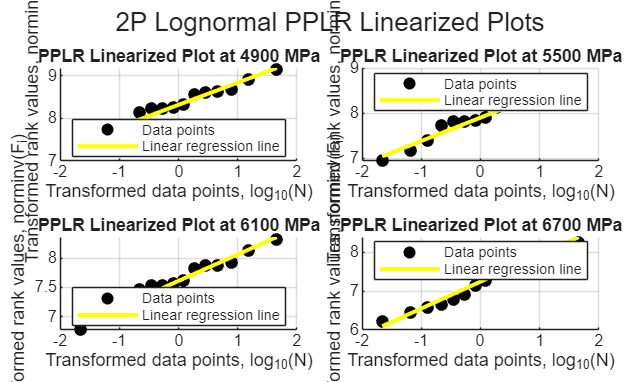

figure('Name','2P Lognormal PPLR Linearized Plots');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for j = 1:num_stress_levels
    nexttile
    scatter(probability_Y{j}, probability_X{j},40, 'k', 'filled');
    hold on;
    plot(probability_Y{j}, probability_Y_fit{j},'y-', 'LineWidth', 2);
    xlabel('Transformed data points, log_{10}(N)');
    ylabel('Transformed rank values, norminv(F_i)');
    title(sprintf('PPLR Linearized Plot at %d MPa',stress_levels(j)));
    legend('Data points', 'Linear regression line', 'Location','best');
    grid on;
    hold off;
end
sgtitle('2P Lognormal PPLR Linearized Plots');

## Check between MATLAB MLE parameter estimates  and PPLR parameter estimates 

%calculate the percentage difference between MATLAB MLE and PPLR estimates

mu_percent_difference = abs(mu_estimates_matlab - mu_estimates_PPLR) ./ abs(mu_estimates_matlab) * 100

mu_percent_difference = 1.0e-13 *

    0.3708
    0.1952
    0.2027
    0.2131


sigma_percent_difference = abs(sigma_estimates_matlab - sigma_estimates_PPLR) ./ abs(sigma_estimates_matlab) * 100

sigma_percent_difference =     9.4578
    9.4547
    9.4451
    8.8381



% display the B1 predictions from PPLR
B1_lives_PPLR = exp(mu_estimates_PPLR + sigma_estimates_PPLR .* norminv(0.01))

B1_lives_PPLR = 1.0e+07 *

    1.2754
    0.4998
    0.3593
    0.0432


## Export analysis results to separate MATLAB file 

save('results_2PL_Steel.mat', ...
    'stress_levels', ...
    'mu_estimates', ...
    'sigma_estimates', ...
    'B1_lives_2PL', ...
    'mu_estimates_matlab', ...
    'sigma_estimates_matlab', ...
    'B1_lives_matlab', ...
    'mu_estimates_PPLR', ...
    'sigma_estimates_PPLR', ...
    'B1_lives_PPLR', ...
    'mu_percent_difference', ...
    'sigma_percent_difference', ...
    'r_max_array', ...
    'rank_equation', ...
    'ad_h', ...
    'p', ...
    'ad_test', ...
    'ad_cv', ...
    'MLE_comparison', ...
    'cdf_x', ...
    'cdf_mle', ...
    'cdf_life_sorted', ...
    'cdf_empirical_F', ...
    'probability_X', ...
    'probability_Y', ...
    'probability_Y_fit', ...
    'pd_2PL_all', ...
    'tail_fit_F_empirical', ...
    'tail_fit_dF_PPLR', ...
    'tail_fit_abs_dF_PPLR', ...
    'tail_fit_lives', 'tail_fit_dF', 'tail_fit_abs_dF');